# Hausaufgabe | Projektpraktikum Matlab

## Einführung I: Pathlen

## Gruppenmitglieder

- Mitglied 1:  Johannes Truong Le (03637523)

- Mitglied 2:  Bernhard Birkner (03637368)

- Mitglied 3:  Sebastian Getz (03623589)

## Allgemeine Hinweise

- Hausaufgaben werden in Gruppen von max. 3 Personen bearbeitet

- Eine gemeinsame Lösung pro Gruppe wird eingereicht

- Jede Datei muss die Namen aller Mitglieder im Header enthalten

- Ihre Lösung der Aufgabe ergänzen Sie in der Datei mit der Aufgabenstellung direkt unterhalb der einzelnen Teilaufgaben. Wird explizit eine Funktion gefordert, liefern Sie diese als *.m-Datei ab

- Textuelle Antworten werden als Text im Live-Editor formatiert

- Code wird im Code-Modus im Live-Editor hinzugefügt

- Abgabe der Lösung erfolgt unter [www.moodle.tum.de](http://www.moodle.tum.de)

## Aufgabenstellung

1) Laden Sie die Datei `A04_Pathlen_coord.txt` in eine Variable [`load`]. Welche Dimensionen hat die Variable?

load = csvread('A04_Pathlen_coord.txt');
%size(load) = [614 2]

2) Interpretieren Sie die Spalten der Variable aus 1) zuerst als kartesische x- und y-Koordinaten von Punkten entlang eines Weges und stellen Sie diesen grafisch dar [`plot`]. Welche Laenge hat der Weg?(Annahmen: lineare Verbindung aufeinanderfolgender Punkte, Einheit [km])

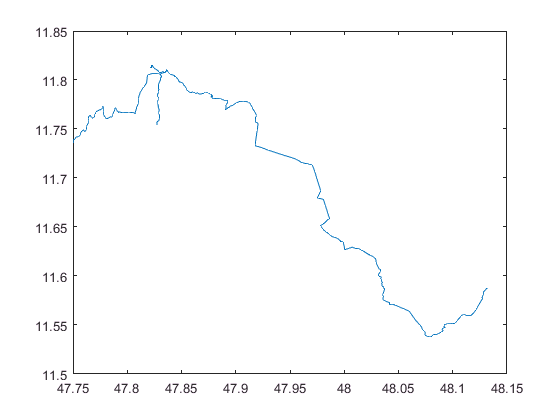

plot(load(:,1),load(:,2));

loadTmp1 = load(1:end-1,:);
loadTmp2 = load(2:end,:); 

distanceWeg = sum(sqrt(sum((loadTmp1-loadTmp2).^2, 2)))

distanceWeg = 0.8806


%distanceWeg = 0.8806 [km]


3) Interpretieren Sie die Spalten der Variable aus 1) nun als geografische Koordinaten (Breite und Laenge) von Punkten entlang eines Weges.  Welche Länge (in [km]) hat der Weg dann? (Annahmen: lineare Verbindung aufeinanderfolgender Punkte, Erdradius konstant 6371 km) Rechnen Sie dazu die geographischen Koordinaten in dreidimensionale kartesische Koordinaten um und summieren Sie die Abstände der aufeinanderfolgenden Punkte.

r = 6371;
load(:,3) = sqrt(r^2 - load(:,1).^2 - load(:,2).^2);

loadTmp3 = load(1:end-1,:);
loadTmp4 = load(2:end,:); 

distanceWeg3D = sum(sqrt(sum((loadTmp3-loadTmp4).^2, 2)))

distanceWeg3D = 0.8806


%distanceWeg3D = 0.8806 [km]

HINWEIS

Die Funktion "distance" darf in dieser Aufgabe NICHT verwendet werden, da diese kein Bestandteil des Standard Matlab-Paket ist, sondern eine Funktion der Neural Network Toolbox.